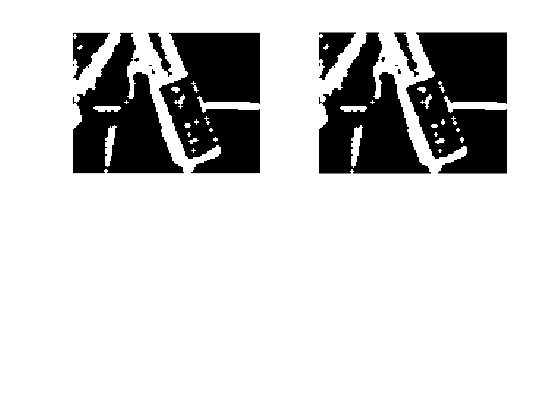

%Build Alpha 1.0 - Improved-Guide Detection (2019-11-23)

%[TestCode, encode] = GenerateCode('zzzzz');

%TestImage1 = imread('im4.jpg');
%TestImage1 = imread('im4.png');
%TestImage1 = imread('image3.png');
TestImage1 = imread("training_1.jpg");
%TestImage1 = imread("test6.jpg");

TestImage1 = imsharpen(TestImage1);

TestImage1 = imresize(TestImage1, 0.2);

TestG = rgb2gray(TestImage1);

L2 = imbinarize(TestG, 'adaptive','ForegroundPolarity','dark','Sensitivity',0.5);
L2 = xor(ones(size(TestG)), L2);

AveFilter = ones(3,3)*1/9;
L2 = imfilter(L2, AveFilter);

se = strel('disk', 1, 8);

L2 = imerode(L2, se);

se = strel('disk', 1, 8);
%L2 = medfilt2(L2);
L2 = imdilate(L2, se);
%imshow(L2);

%Find regions
s = regionprops(L2,{...
    'Area', ...
    'Centroid',...
    'MajorAxisLength',...
    'MinorAxisLength',...
    'Orientation', ... 
    'Solidity'});

TotalShapes = length(s);

Guidelines = struct;
GuidelinesS = struct;
GuidelinesL = struct;
Cornerstones = struct;

% GuidelinesS.Centroid = [0 0];
% GuidelinesS.MajorAxisLength = 0;
% GuidelinesS.MajorAxisLength = 0;
% GuidelinesS.Orientation = 0;

MinSRatio = 3;
MaxSRatio = 10;

MinLRatio = 6;
MaxLRatio = 10;

PotentialGuideS = 0;
PotentialGuideL = 0;
PotentialCornerstones = 0;

for i = 1:TotalShapes
    Shape = s(i);
    ShapePos = Shape.Centroid;
    ShapeLength = Shape.MajorAxisLength;
    ShapeWidth = Shape.MinorAxisLength;
    ShapeAngle = Shape.Orientation;
    ShapeSolid = Shape.Solidity;
    
    %Get Ratio
    ShapeRatio = ShapeLength/ShapeWidth;
    
    %Store Guides
    if ShapeRatio > MinSRatio && ShapeRatio < MaxSRatio && ShapeSolid > 0.6 && Shape.Area > 6
        PotentialGuideS = PotentialGuideS + 1;

        GuidelinesS(PotentialGuideS).Centroid = ShapePos;
        GuidelinesS(PotentialGuideS).MajorAxisLength = ShapeLength;
        GuidelinesS(PotentialGuideS).MinorAxisLength = ShapeWidth;
        GuidelinesS(PotentialGuideS).Orientation = ShapeAngle;
        GuidelinesS(PotentialGuideS).Solidity = ShapeSolid;
        
%     elseif ShapeRatio > MinLRatio && ShapeRatio < MaxLRatio && ShapeSolid > 0.6 && Shape.Area > 6
%         PotentialGuideL = PotentialGuideL + 1;
%         GuidelinesL(PotentialGuideL).Centroid = ShapePos;
%         GuidelinesL(PotentialGuideL).MajorAxisLength = ShapeLength;
%         GuidelinesL(PotentialGuideL).MinorAxisLength = ShapeWidth;
%         GuidelinesL(PotentialGuideL).Orientation = ShapeAngle;
%         GuidelinesL(PotentialGuideL).Solidity = ShapeSolid;
        
    else
        %Check cornerstones
        if ShapeRatio > 0.7 && ShapeRatio < 1.2 && ShapeSolid > 0.6 && Shape.Area > 6
            PotentialCornerstones = PotentialCornerstones + 1;
            
            Cornerstones(PotentialCornerstones).Centroid = ShapePos;
            Cornerstones(PotentialCornerstones).MajorAxisLength = ShapeLength;
            Cornerstones(PotentialCornerstones).MinorAxisLength = ShapeWidth;
            Cornerstones(PotentialCornerstones).Orientation = ShapeAngle;
            Cornerstones(PotentialCornerstones).Solidity = ShapeSolid;
        end

    end
end

PotentialMarkers = 0;
Guides = struct;

%Verify Guides
for GuideS = 1:PotentialGuideS
    S = GuidelinesS(GuideS);
    SPos = S.Centroid;
    SLength = S.MajorAxisLength;
    SWidth = S.MinorAxisLength;
    SAngle = S.Orientation;
    %SSolid = Shape.Solidity;
    
    %Look for matching long guide
    for GuideL = 1:PotentialGuideS
        L = GuidelinesS(GuideL);
        LPos = L.Centroid;
        LLength = L.MajorAxisLength;
        LWidth = S.MinorAxisLength;
        LAngle = L.Orientation;
        
        
        AveWidth = (SWidth + LWidth)/2;
        
        dRatio = LLength/SLength;
        dGuide = norm(SPos - LPos);
        dAngle = abs(SAngle - LAngle);
        
        Min = 2.5*AveWidth;
        Max = 8*AveWidth;
        
        if dGuide >=  Min && dGuide <  Max ...
            && dAngle > 75 && dAngle < 100 ...
            && dRatio > 1.1 && dRatio < 1.6
        
            PotentialMarkers = PotentialMarkers + 1;
            
            Guides(PotentialMarkers).SGuide = GuidelinesS(GuideS);
            Guides(PotentialMarkers).LGuide = GuidelinesS(GuideL);
            
        end
    end
end

ConfirmedMarkers = 0;

%Find Cornerstones
for G = 1:PotentialMarkers
    GuideS = Guides(G).SGuide;
    GuideL = Guides(G).LGuide;
    
    for A = 1:PotentialCornerstones
        for B = 1:PotentialCornerstones
            for C = 1:PotentialCornerstones
                APos = Cornerstones(A).Centroid;
                BPos = Cornerstones(B).Centroid;
                CPos = Cornerstones(C).Centroid;
                
                AveWidth = (Cornerstones(A).MinorAxisLength + Cornerstones(B).MinorAxisLength ...
                            + Cornerstones(C).MinorAxisLength)/3;
                
                dAB = norm(APos - BPos);
                dAC = norm(APos - CPos);
                dCB = norm(CPos - BPos);
                dCS = norm(CPos - GuideS.Centroid);
                dBL = norm(BPos - GuideL.Centroid);
                
                Angle = acos((dAB^2 + dAC^2 - dCB^2)/(2*dAB*dAC))*180/pi;
                
                MinSide = 7*AveWidth;
                MaxSide = 12*AveWidth;
                
                MinDiag = 10*AveWidth;
                MaxDiag = 17*AveWidth;
                
                MinL = 3*AveWidth;
                MaxL = 7*AveWidth;
                
                MinS = 6*AveWidth;
                MaxS = 10*AveWidth;
                
                if dAB > MinSide && dAB < MaxSide 
                    if dAC > MinSide && dAC < MaxSide 
                        if dCB > MinDiag && dCB < MaxDiag 
                            if dCS > MinS && dCS < MaxS  
                                if dBL > MinL && dBL < MaxL ...
                                    && Angle > 75 && Angle < 100
                    
                                ConfirmedMarkers = ConfirmedMarkers + 1;
                           
                                Guides(G).A = Cornerstones(A);
                                Guides(G).B = Cornerstones(B);
                                Guides(G).C = Cornerstones(C);
                                end
                            end
                        end
                    end
                end
            end
        end
    end
end
subplot(2,2,1);
imshow(L2);

SamplingGrid = zeros(11,11,2);

%Plot markers
subplot(2,2,2);
imshow(L2);
hold on

for i = 1:PotentialMarkers
    Pos1 = Guides(i).SGuide.Centroid;
    Pos2 = Guides(i).LGuide.Centroid;
    Pos3 = Guides(i).A.Centroid;
    Pos4 = Guides(i).B.Centroid;
    Pos5 = Guides(i).C.Centroid;
    
    VectorX = SampleInterval(Pos3, Pos4, 11);
    VectorY = SampleInterval(Pos3, Pos5, 11);
    VectorZ = SampleInterval(Pos4, Pos1, 11);
    VectorA = SampleInterval(Pos5, Pos1, 9);
    
    %Generate Inbetween sampling points
    for k = 2:11
        P1 = [VectorY(1,k) VectorY(2,k)];
        P2 = [VectorZ(1,k) VectorZ(2,k)];
        
        if k <= 4
            NumSample = 11;
        elseif k>4 && k <= 8
            NumSample = 10;
        else
            NumSample = 9;
        end
        
        SampleVector = SampleInterval(P1, P2, NumSample);
        
        SamplingGrid(k, :, 1) = SampleVector(1, :);
        SamplingGrid(k, :, 2) = SampleVector(2, :);
    end
    
    SamplingGrid(1, :, 1) = VectorX(1, :);
    SamplingGrid(1, :, 2) = VectorX(2, :);
    
    for j = 1:11
        for k = 1:11
            plot(SamplingGrid(j,k,1), SamplingGrid(j,k,2), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
            
            
        end
    end
    
    
%     for j = 1:length(Vector)
%         plot(VectorX(1, j), VectorX(2,j), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
%         plot(VectorY(1, j), VectorY(2,j), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
%         plot(VectorZ(1, j), VectorZ(2,j), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
%         
%         if j <= 8
%             plot(VectorA(1, j), VectorA(2,j), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
%     
%         end
%     end
%     plot(Pos1(1), Pos1(2), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
%     plot(Pos2(1), Pos2(2), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
%     plot(Pos3(1), Pos3(2), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
%     plot(Pos4(1), Pos4(2), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
%     plot(Pos5(1), Pos5(2), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
end

Reference to non-existent field 'A'.

hold off

Code = uint8(zeros(11,11));

%Get marker
for i = 1:11
    for j = 1:11
        PixelR = SamplingGrid(i,j,2);
        PixelC = SamplingGrid(i,j,1);
        
        if PixelR > 0 && PixelC > 0
            Code(i,j) = ~(L2(SamplingGrid(i,j,2), SamplingGrid(i,j,1)));
        end
    end
end
subplot(2,2,3);
imshow(Code, []);
Msg = (QRDecode(Code));
title(Msg);